# Интерполяция. Сплайны

## Пример (мотивация использовать сплайны)

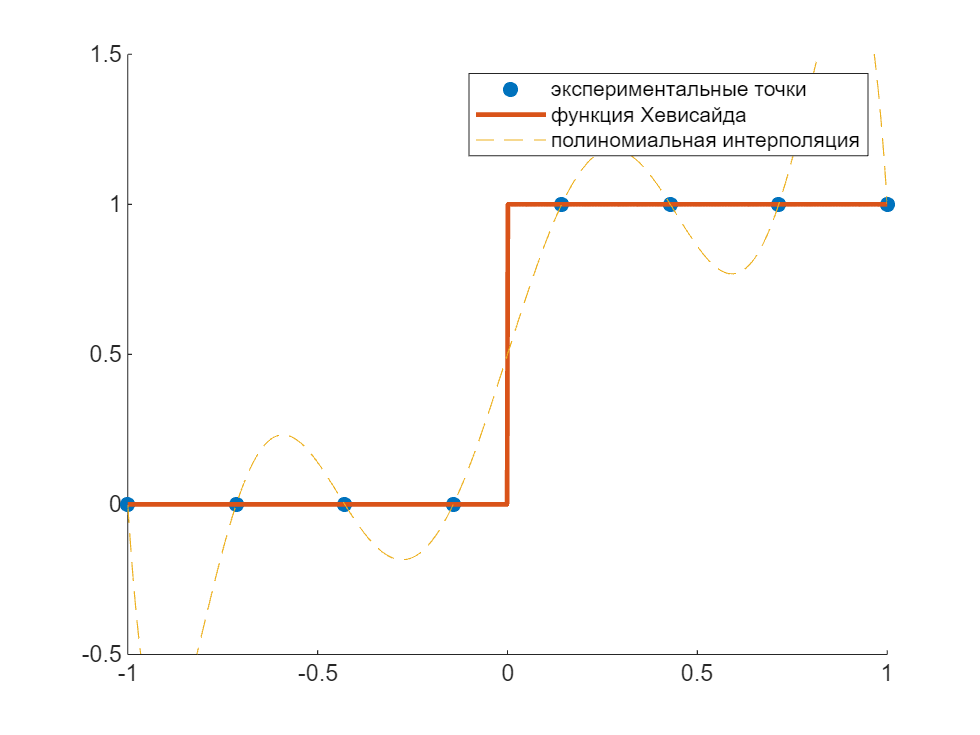

N = 8; % меняем количество "экспериментальных точек"
x = linspace(-1,1,N);
y = heaviside(x);

%полиномиальная интерполяция
p = polyfit(x,y,N-1); % коэффициенты полиномов
yp = polyval(p,linspace(-1,1,1000)); % значение интерполяции


% Рисуем графики
scatter(x,y, DisplayName="экспериментальные точки", MarkerFaceColor="flat")
hold on
plot(linspace(-1,1,1000), heaviside(linspace(-1,1,1000)),DisplayName="функция Хевисайда", LineWidth=2)
plot(linspace(-1,1,1000), yp, DisplayName="полиномиальная интерполяция", LineStyle="--")
legend
ylim([-0.5,1.5])
hold off

## Линейные сплайны

Для n экспериментальных точек $(i = 1, 2, 3, ..., n)$ у нас будет иметься $(n-1)$ интервалов. У каждого интервала будет своя функция $s_i(x)$. Если мы имеем дело с линейными сплайнами, то функция 


$$s_i(x) = a_i+b_i(x-x_i)$$


коэффициенты $a_i = f_i$ (пересечение)

коэффициенты $b_i = \frac{f_{i+1}-f_i}{x_{i+1}-x_i}$ (пересечение)

следовательно вид функции будет выглядеть следующим образом 


$$s_i(x) = a_i+b_i(x-x_i) = f_i+\frac{f_{i+1}-f_i}{x_{i+1}-x_i}(x-x_i)$$


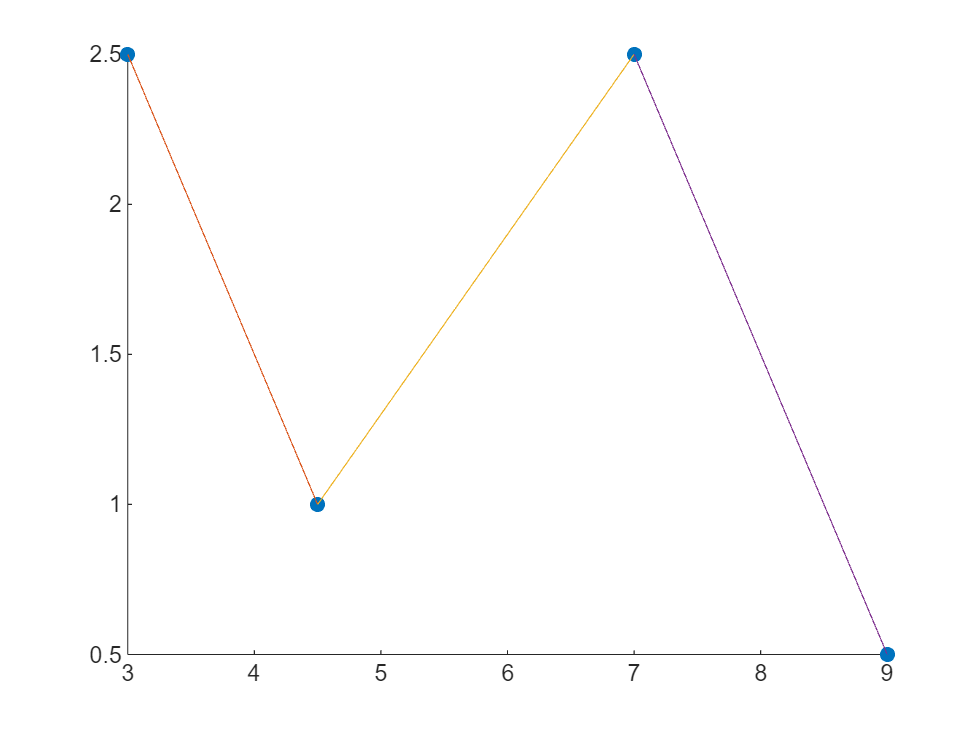

% пример реализации линейных сплайнов
clearvars;
x = [3, 4.5, 7.0, 9.0];
y = [2.5, 1.0, 2.5, 0.5];

xp1 = linspace(3,4.5,100);
xp2 = linspace(4.5,7,100);
xp3 = linspace(7.0,9,100);

%построим s_i(x)
s1 = @(xp) y(1)+(y(2)-y(1))/(x(2)-x(1))*(xp-x(1));
s2 = @(xp) y(2)+(y(3)-y(2))/(x(3)-x(2))*(xp-x(2));
s3 = @(xp) y(3)+(y(4)-y(3))/(x(4)-x(3))*(xp-x(3));

%Нарисуем графики
scatter(x,y, MarkerFaceColor="flat", DisplayName="экспериментальные точки")
hold on
plot(xp1,s1(xp1))
plot(xp2,s2(xp2))
plot(xp3,s3(xp3))
hold off

Минусы линейных сплайнов состоит в том, что итоговый сплайн не является гладким. 

## Квадратичные и кубические сплайны

Для простоты рассмотрим уравнения для квадратичных сплайнов

функция для интервала будет выглядеть следующим образом 


$$s_i(x) = a_i+b_i(x-x_i)+c_i(x-x_i)^2$$


найдем коэффициенты. 

Для n экспериментальных точек $(i = 1,2,3,...n)$ у нас $n-1$ интервал и $3(n-1) $ коэффициентов (a,b,c). То есть нам надо составить $3(n-1) $ уравнений

- функция должна проходить через все точки (условие непрерывности)


$$f_i = a_i +b_i(x_i-x_i)+c_i(x_i-x_i)^2 = a_i$$



$$a_i = f_i$$


Итого мы нашли $(n-1) $ уравнений. Осталось $2(n-1) $

- значения соседних функций должны быть равны в узлах


$$f_i+b_i(x_{i+1}-x_i)+c_i(x_{i+1}-x_i)^2 = f_{i+1}+b_{i+1}(x_{i+1}-x_{i+1})+c_{i+1}(x_{i+1}-x_{i+1})^2 $$


определим шаг $h_i = x_{i+1}-x_{i}$

перепишем и получим


$$f_i+b_ih_i+c_ih_i^2= f_{i+1}$$


таких уравнений мы можем составить $n-1
$ штук. Значит нам остается составить $(n-1) $ уравнений

- Первые производные должны быть на внутренних узлах должны быть одинаковы. Это важное условие для того, чтобы соседние сплайны объединялись гладким образом. 


$$s_i ' = b_i+2c_i(x-x_i)$$


По аналогии мы должны составить уравнения для соседних нод i и i+1


$$b_i+2c_ih_i = b_{i+1}$$


Таких условий у нас $(n-2) $. То есть остается у нас $n-1-(n-2) = n-1+n+2 = 1$. Одно условие

- Предположим, что вторая производная в первой точке равна нулю, получим


$$s_i'' = 2c_i $$



$$s_1'' = 2c_1 = 0 \Rightarrow c_1 = 0$$


Мы определили уравнения для всех коэффициентов. 

Для кубического сплайна все тоже самое, просто немного сложнее

Наше уравнение 


$$s_i(x) = a_i+b_i(x-x_i)+c_i(x-x_i)^2+d_i(x-x_i)^3$$


У нас также n экспериментальных точек $(i =1,2,...n)$. Число интервалов $n-1$. Число уравнений, чтобы найти все коэффициенты $4(n-1)$